clear
targetImage = im2double(imread("dogdogorange.png"));
imagefiles = dir("data64\test\animal animal_faces cat cat_face\*.jpg")

imagefiles = 1650×1 struct array with fields:
    name
    folder
    date
    bytes
    isdir
    datenum


filepath = "data64\test\animal animal_faces cat cat_face"

filepath = "data64\test\animal animal_faces cat cat_face"


rTileSize = 64;
oTileSize = 16;

[rows, cols, ~] = size(targetImage)

rows = 867

cols = 701

tileRows = ceil(rows / oTileSize)

tileRows = 55

tileCols = ceil(cols / oTileSize)

tileCols = 44

numberOfTiles = tileRows * tileCols;
averageWantedColours = zeros(numberOfTiles, 3);
counter = 1

counter = 1

for c = 1:tileCols
    for r = 1:tileRows
        tileRFrom = 1 + (r-1)*(oTileSize);
        tileRTo = r*oTileSize;
        if tileRTo > rows
            tileRTo = rows;
        end
        tileCFrom = 1 + (c-1)*(oTileSize);
        tileCTo = c*oTileSize;
        if tileCTo > cols
            tileCTo = cols;
        end
        currentTile = targetImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :);

        averageWantedColours(counter,:) = averageColourXYZ(currentTile);
        
        counter = counter + 1;
    end
end

averageWantedColours

averageWantedColours =    60.8712   62.8774   57.5938
   61.1542   63.0515   58.5093
   61.9299   63.8785   59.3206
   61.9792   63.9928   59.1445
   63.3056   65.3247   60.9182
   63.7050   66.1192   61.5750
   63.6542   65.8402   62.4800
   62.2379   64.9376   60.2390
   55.3367   59.1543   50.4295
   44.0697   48.3055   37.3803



for ii=1:1000
   currentfilename = imagefiles(ii).name;
   currentimage = im2double(imread(filepath + "\" +  currentfilename));
   images{ii} = currentimage;
end

wantedNumberOfImages = 500

wantedNumberOfImages = 500

[~, numberOfImages] = size(images);
threshold = 2;
imagesFiltered = {};
for image = 1:numberOfImages
    %convert to XYZ
    currentImageXYZ = averageColourXYZ(images{image});
    for tile = 1:numberOfTiles
        % use calcDeltaE
        [meanDeltaE, ~] = calcDeltaE(averageWantedColours(tile,:), currentImageXYZ');
        % if the image could be useful add it
        if meanDeltaE < threshold
            imagesFiltered{end+1} = images{image};
            break
        end
    end
end

imagesFiltered

imagesFiltered = 1×862 cell array
    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {64×64×3 double}    {6

[~, datasetSize] = size(imagesFiltered)

datasetSize = 862

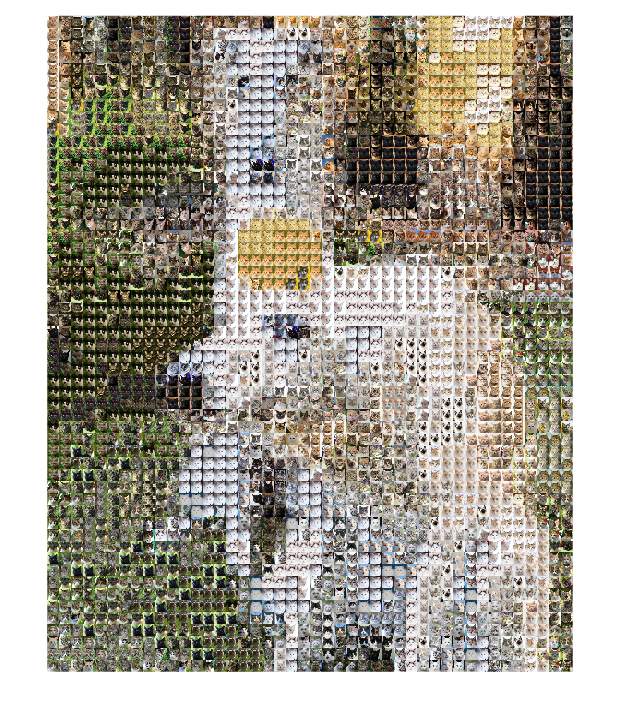

processbar = waitbar(0, 'Processing Images...');
% go through each tile
for c = 1:tileCols
    for r = 1:tileRows
        tileRFrom = 1 + (r-1)*(oTileSize);
        tileRTo = r*oTileSize;
        if tileRTo > rows
            tileRTo = rows;
        end
        tileCFrom = 1 + (c-1)*(oTileSize);
        tileCTo = c*oTileSize;
        if tileCTo > cols
            tileCTo = cols;
        end
        currentTile = targetImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :);

        % convert current Tile to xyz, might use average colour
        averageTileXYZ = averageColourXYZ(currentTile);

        
        bestImageIndex = 0;
        bestDeltaE = 1000;

        waitbar(c/tileCols, processbar, "bonking kitties...");

        % find best image for each tile
        for i = 1:datasetSize
            
            curImg = imagesFiltered{i};
            % convert current sample image to xyz

            %imshow(curImg)
            currentImageXYZ = averageColourXYZ(curImg);


            % use calcDeltaE
            [meanDeltaE, Max] = calcDeltaE(averageTileXYZ', currentImageXYZ');


            if Max < bestDeltaE
                bestDeltaE = Max;
                bestImageIndex = i;
            end


            averageTileXYZ;
            currentImageXYZ;
            Max;
            i;
            bestImageIndex;

        end
        tileRFrom = 1 + (r-1)*(rTileSize);
        tileRTo = r*rTileSize;
        tileCFrom = 1 + (c-1)*(rTileSize);
        tileCTo = c*rTileSize;
        outputImage(tileRFrom:tileRTo, tileCFrom:tileCTo, :) = imagesFiltered{bestImageIndex};
    end
end
close(processbar)

imshow(outputImage)